%[y x1 x2]
  A=[80750.67983207744 24.817574516788952 1;
   33842.079470753873 23.825936382302192 0;
   194891.66932077392 23.268858402065369 1;
   15359.851544095609 21.030399174664652 1;
   64627.861059016643 23.704123793069336 0;
   34716.982870117215 23.77441539597471 0;
   26389.594392983439 24.81798320776792 0;
   212050.82646712702 27.95619562877393 0;
   106562.10472443166 26.913936961708149 0;
   386231.12334980676 28.497900986527739 1;
   37443.08337862941 25.122825258965264 0;
   65803.947236528023 28.550334084373336 0;
   35645.20344913489 24.654415467595264 0;
   22578.862223847584 22.648485977635783 0;
   84982.349041792477 26.294842137299753 0;
   48289.449189191306 25.627341189419198 0;
   242113.74753331198 25.411564676448855 1;
   23743.041118853296 23.933114393184741 0;
   119344.8891157014 24.20462371266418 1;
   15829.088847510799 21.371219777344184 1;
   47676.41669545789 22.921778784952238 1;
   19388.610568250097 20.073232131846215 1;
   359120.91922456573 29.327012247765065 0;
   70009.02286133208 26.092585410840297 0;
   686221.103911334 28.918456938262793 1;
   60557.485437015755 24.20824840285832 0;
   150665.64756441588 24.001813440136246 1;
   41530.151174548868 25.539341179688915 0;
   199256.16339654507 25.962594382507731 1;
   98595.985965528133 25.062788211049885 0];
y=A(:,1);
x1=A(:,2);
x2=A(:,3);

scatter(x1, y, 'blue', '+')
corr(x1, y)

ans = 0.6459

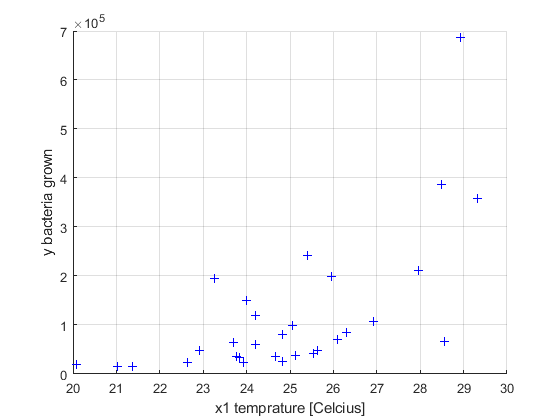

xlabel('x1 temprature [Celcius]')
ylabel('y bacteria grown')
grid on

logy = log(y);
corr(x1, logy)

ans = 0.7404

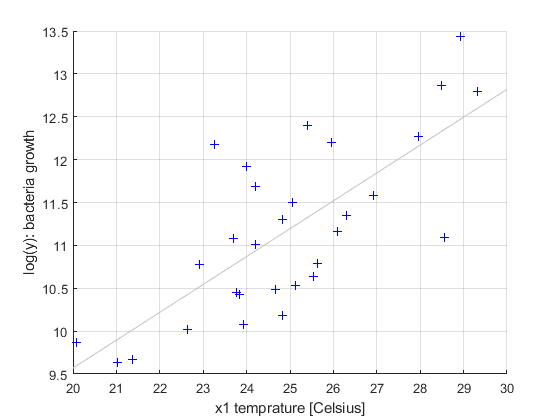

scatter(x1, logy, 'blue', '+');
xlabel('x1 temprature [Celsius]')
ylabel('log(y): bacteria growth')
grid on
lsline
print -depsc pngFig

regr_transformed = regstats(logy, [x1 x2], 'linear', 'all');
regr_transformed.beta

ans =     1.1720
    0.3849
    1.0057


regr_transformed.rsquare

ans = 0.7812

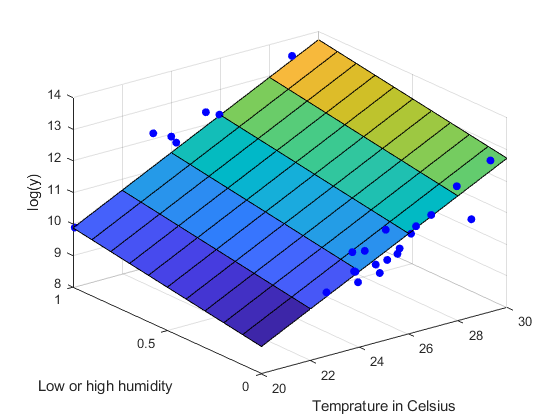

scatter3(x1, x2, logy, 'blue', 'filled')
hold on;
[x_grid1, x_grid2]=meshgrid(0:0.1:1,20:2:30);
beta1 = regr_transformed.beta;
y1=beta1(1)+beta1(2)*x_grid2+beta1(3)*x_grid1;
surf(x_grid2, x_grid1, y1);
xlabel('Temprature in Celsius')
ylabel('Low or high humidity')
zlabel('log(y)')
hold off

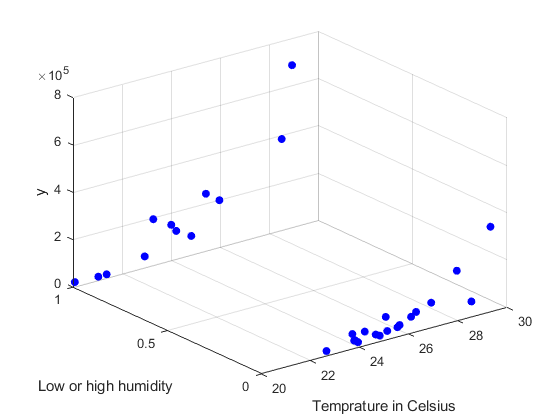



scatter3(x1, x2, y, 'blue', 'filled')
xlabel('Temprature in Celsius')
ylabel('Low or high humidity')
zlabel('y')

print -depsc pngFig

X = [];

X(:,1) = ones(30,1);
X(:, 2) = x1;
X(:, 3) = x2;
X

X =     1.0000   24.8176    1.0000
    1.0000   23.8259         0
    1.0000   23.2689    1.0000
    1.0000   21.0304    1.0000
    1.0000   23.7041         0
    1.0000   23.7744         0
    1.0000   24.8180         0
    1.0000   27.9562         0
    1.0000   26.9139         0
    1.0000   28.4979    1.0000



K = inv(X'*X)

K =     4.7138   -0.1831   -0.2827
   -0.1831    0.0072    0.0089
   -0.2827    0.0089    0.1500


regr_transformed.fstat.sse

ans = 6.3304

s = sqrt(regr_transformed.fstat.sse/(27))

s = 0.4842

t = 2.0518;
u = [1 25 0]';

lowerbound = u'*beta1 - t*s*sqrt(u'*K*u+1)

lowerbound = 9.7739

upperbound = u'*beta1 + t*s*sqrt(u'*K*u+1)

upperbound = 11.8167

format short g
exp(lowerbound)

ans =         17569


format short g
exp(upperbound)

ans =     1.355e+05
